clearvars
%define the grid
Nx = 600;%600
Ny = 450;%450
dx = 2e-4;%2e-4
dy = 2e-4;%2e-4
%Kgrid = kWaveGrid(Nx,dx,Ny,dy);


%Use point per wavelength ppl to reduce dx until stable
%dx = 2e-4 ppl = 37500
%relation of CFL
dt = 4E-8

dt = 4.0000e-08

CFL = 1500*dt/dx

CFL = 0.3000

%calculation for ppw,dx,Nx
points_per_wavelength = 2

points_per_wavelength = 2

dx_old = 1500/(points_per_wavelength*3.75e6)

dx_old = 2.0000e-04

fre = 3.75e6

fre = 3750000

ppw = 1500/(fre*2e-4)

ppw = 2

%Nx = round(0.12/dx)

%change ppw,dx,dy
ppw_new = 8

ppw_new = 8

dx_new = 1500/(fre*ppw_new)

dx_new = 5.0000e-05

dy_new = dx_new

dy_new = 5.0000e-05

dt_new = 0.3*dx_new/1500

dt_new = 1.0000e-08

Nx_new = 0.12/dx_new

Nx_new = 2400

Ny_new = round(0.09/dy_new)

Ny_new = 1800

Kgrid = kWaveGrid(Nx_new,dx_new,Ny_new,dy_new);





%define the medium prperty
medium.sound_speed = 1500;
medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;

% create the time array
Kgrid.makeTime(medium.sound_speed,0.3,5e-5);%128SQRT2/1500
%t_array_new = Kgrid.t_array(1:126)
t_array_new = [0:dt_new:0.5e-5]

t_array_new = 1.0e-05 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


Kgrid.t_array

ans = 1.0e-04 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


% define a single source point
source.p_mask = zeros(Nx_new, Ny_new);
source.p_mask(70/120*Nx_new, Ny_new/2) = 1;

% define a time varying sinusoidal source
source_freq = 1e6;   % [Hz]
source_mag = 3;         % [Pa]
source.p = source_mag * sin(2 * pi * source_freq * t_array_new);
%% 

% filter the source to remove high frequencies not supported by the grid
%source.p = filterTimeSeries(Kgrid, medium, source.p);

%define the sensor in a line
x_offset = 20/120*Nx_new % [grid points]

x_offset = 400

width = 50/90*Ny_new% [grid points]

width = 1000

sensor.mask = zeros(Nx_new, Ny_new);
inch = width/32

inch = 31.2500

sensor.mask(x_offset, Ny_new/2 - width/2 + 1:inch:Ny_new/2 + width/2) = 1;

sensor.mask

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

Running k-Wave simulation...
  start time: 07-Mar-2023 23:11:04
  reference sound speed: 1500m/s
  dt: 10ns, t_end: 50us, time steps: 5001
  input grid size: 2400 by 1800 grid points (120 by 90mm)
  maximum supported frequency: 15MHz
  precomputation completed in 0.27856s
  starting time loop...
  estimated simulation time 54min 1.2481s...


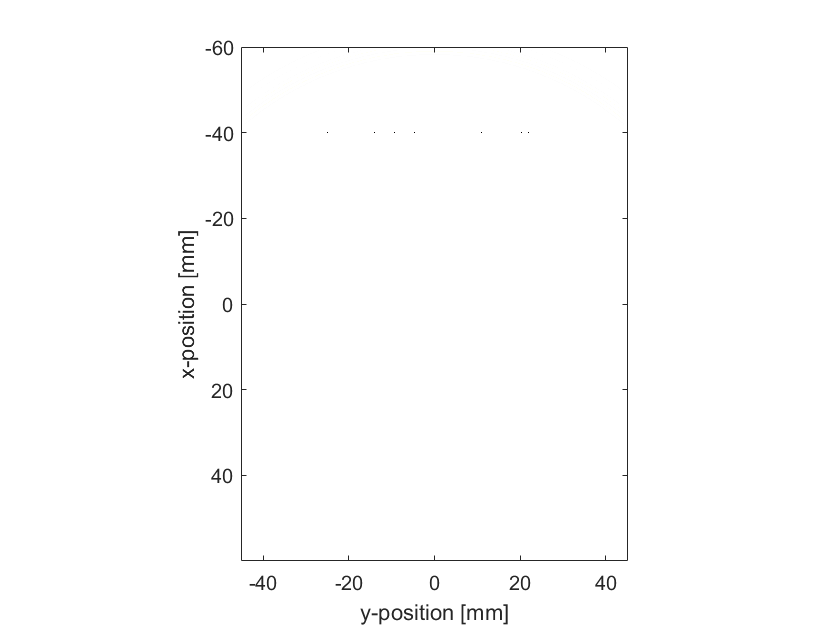

  simulation completed in 49min 21.4258s
  total computation time 49min 21.767s



% run the simulation
sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);

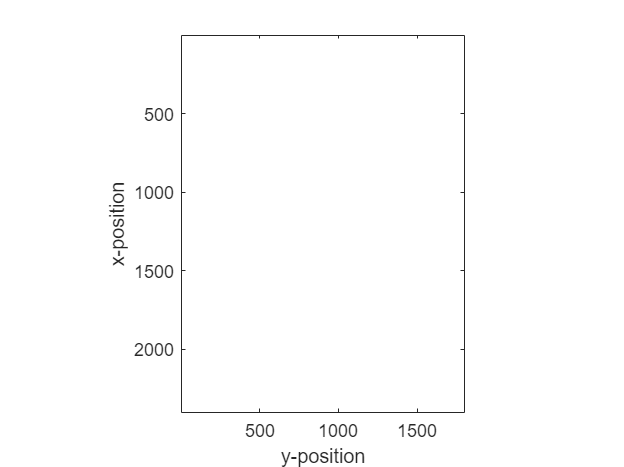


% VISUALISATION
% =========================================================================

% plot the initial pressure and sensor distribution
%positive max around 0.043-0.0449
figure;
%imagesc(Kgrid.y_vec * 1e3, Kgrid.x_vec * 1e3, source.p0 + cart2grid(Kgrid, sensor.mask), [-1, 1]);
imagesc(source.p_mask + sensor.mask, [-1, 1]);
%imagesc(source.p0 + sensor.mask, [-1, 1]);
colormap(getColorMap);
ylabel('x-position');
xlabel('y-position');
axis image;

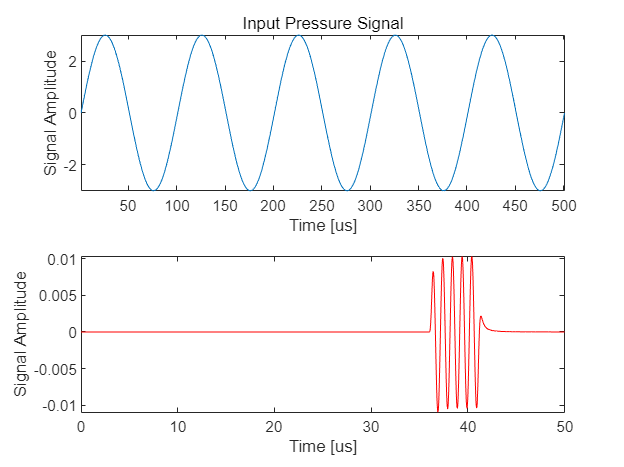

%% 

% plot the simulated sensor data
figure;
[t_sc, scale, prefix] = scaleSI(max(Kgrid.t_array));

subplot(2, 1, 1);
plot(source.p)
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([-inf,inf,-inf,inf]);
title('Input Pressure Signal');

subplot(2, 1, 2);
plot(Kgrid.t_array * scale, sensor_data(3,:), 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');

%axis ([0,100,-0.05,0.05]);
%axis tight;
%axis([0,10.5,-inf,inf]);



% plot the simulated sensor data
figure;
[t_sc, scale, prefix] = scaleSI(max(t_array_new));
Kgrid.t_array

ans = 1.0e-04 *

         0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


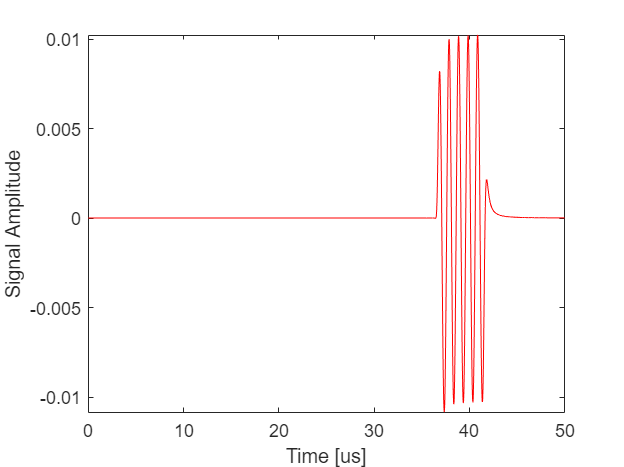

plot(Kgrid.t_array * scale, sensor_data(32,:), 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([-inf,inf,-inf,inf]);
axis tight;

%axis([0,10.5,-inf,inf]);


minx = min(sensor_data(1,:))

minx = -0.0107

maxx = max(sensor_data(1,:))

maxx = 0.0101

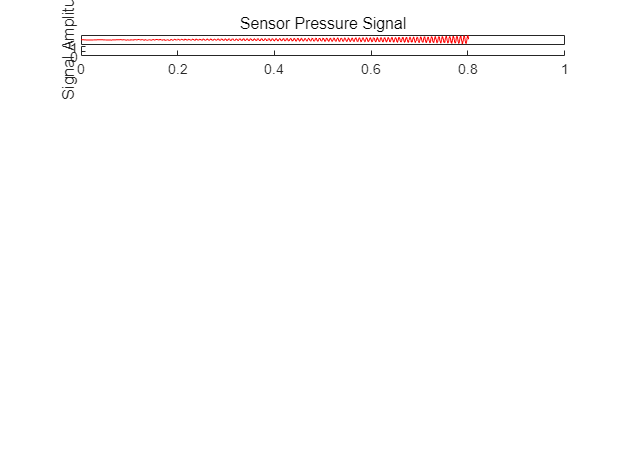

Index in position 1 exceeds array bounds. Index must not exceed 1.

%plot all the 32 original sensor signal 
figure
for i = 1:32
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data(i,:), 'r-');

    %axis([0,10.5,-inf,inf]);
    set(gca,'XTick',[],'YTick',[]);
    if i == 1
            %xlabel(['Time [' prefix 's]']);
            ylabel('Signal Amplitude');
            title('Sensor Pressure Signal');
    end
    if i == 32 
        xlabel(['Time [' prefix 's]']);
        %ylabel('Signal Amplitude');
        %title('Sensor Pressure Signal');
    end

end

%% dt=40ns tend=100.04us timestep = 2502 totalt=1e-4
Kgrid.t_array
t_array_limit = 1/source_freq*5
t_array_new = Kgrid.t_array(1:32)
1/2E-4
128*1.414/1500



%obtian all the sensor position
sensorpoistion = zeros(1,32)

sensorpoistion =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sensorpoistion(2)

ans = 0

j=1

j = 1

for i = 1:450
    if sensor.mask(100,i)==1
        
        sensorpoistion(j) = i;
        j = j+1;
    end
end
sensorpoistion()

ans =    101   109   117   124   132   140   148   156   164   171   179   187   195   203   210   218   226   234   242   249   257   265   273   281   289   296   304   312   320   328   335   343


%distance from sensor to source mm
distance = zeros(1,32);
sourceposition =[70/120*Nx, Ny/2]%x=350,y=225

sourceposition =    350   225



for i = 1:32
    distance(i) = sqrt((sensorpoistion(i)-225)^2+(350-100)^2);
end

%source strength = 4pi/N*sum(distance*signal)
c = 1500;
distance

distance =   279.0627  275.6012  272.3307  269.6312  266.7377  264.0549  261.5894  259.3473  257.3344  255.7655  254.1968  252.8715  251.7936  250.9661  250.4496  250.0980  250.0020  250.1619  250.5773  251.1494  252.0397  253.1798  254.5663  256.1952  258.0620  259.8865  262.1850  264.7055  267.4416  270.3868  273.1300  276.4489


%the propagation time from location x to sensor j
tj = distance*dx/c%unit:s

tj = 1.0e-04 *

    0.3721    0.3675    0.3631    0.3595    0.3557    0.3521    0.3488    0.3458    0.3431    0.3410    0.3389    0.3372    0.3357    0.3346    0.3339    0.3335    0.3333    0.3335    0.3341    0.3349    0.3361    0.3376    0.3394    0.3416    0.3441    0.3465    0.3496    0.3529    0.3566    0.3605    0.3642    0.3686


coeff = 4/32*pi

coeff = 0.3927

%distance_total = sum(distance, 'all')


%Shift test
%1st calculate how much time step to move
% step = tj(1)/4e-8%how many step to move
% step = floor(step)
% sensor_data_test = sensor_data(1,:)
% sensor_data_new = circshift(sensor_data_test, -step)

%shift test2
% function [AfterArray] = ArrayDisplacement(BeforeArray,direction,len,type)
% ArrayEnd = length(BeforeArray);
% eforeArrayL = BeforeArray(1:len);
% BeforeArrayR = BeforeArray(len+1:ArrayEnd);
% BeforeArrayL = fliplr(BeforeArrayL);
% BeforeArrayR = fliplr(BeforeArrayR);
% BeforeArray = [BeforeArrayL BeforeArrayR];
% AfterArray = fliplr(BeforeArray);

%apply the time delay to the sensor data
step = zeros(1,32)

step =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


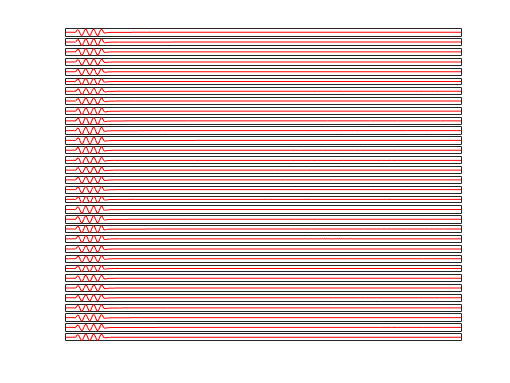

sensor_data_test = zeros(32,1251);
sensor_data_new = zeros(32,1251);
for i = 1:32
    step(i) = floor(tj(i)/4e-8);
    sensor_data_test(i,:) = sensor_data(i,:);
    sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
    %plot the shifted data 
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data_new(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
    %axis([0,10.5,-inf,inf]);
end

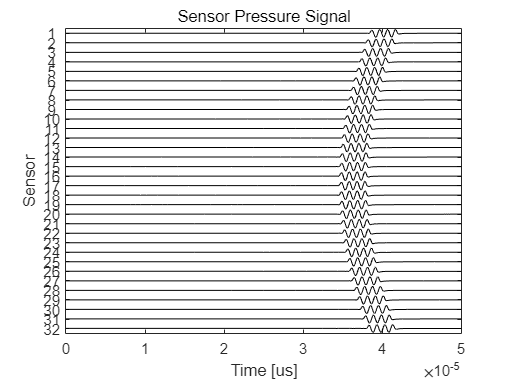

figure

stackedPlot(Kgrid.t_array,sensor_data)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

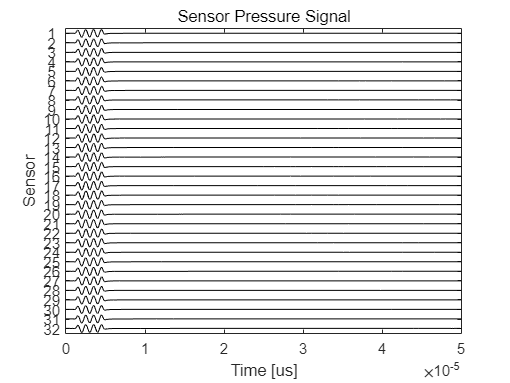


figure
stackedPlot(Kgrid.t_array,sensor_data_new)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

%calculate intensity
figure
A = zeros(32,1251)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

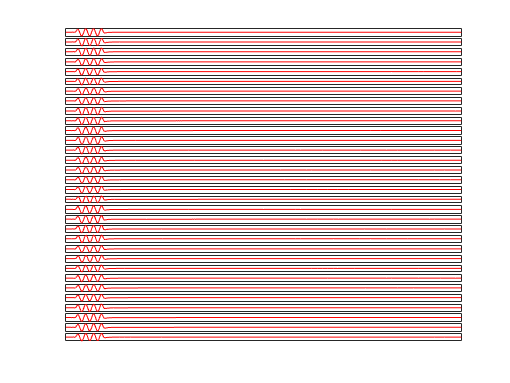

A(1,:) = distance(1)*sensor_data_new(1,:);
for i = 1:32
    A(i,:) = distance(i)*sensor_data_new(i,:);
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, A(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
end

figure
sum_A = sum(A)

sum_A =    -0.0084    0.0209    0.0246   -0.0018   -0.0388   -0.0599   -0.0527   -0.0262    0.0023    0.0259    0.0536    0.0939    0.1293    0.1056   -0.0452   -0.3518   -0.7476   -1.0524   -1.0188   -0.4456    0.6795    2.0687    3.1262    3.0895    1.3179   -2.3328   -7.1629  -11.4458  -12.5287   -7.2690    7.2413   32.8244   69.4738  114.9588  164.9288  213.5176  254.2933  281.3051  289.9798  277.7084  244.0742  190.7690  121.2801   40.4353  -46.1189 -132.4375 -212.7381 -281.7649 -335.0573 -369.1534


%plot(Kgrid.t_array * scale, sum_A, 'r-');
intensity = coeff * sum_A

intensity =    -0.0033    0.0082    0.0097   -0.0007   -0.0152   -0.0235   -0.0207   -0.0103    0.0009    0.0102    0.0211    0.0369    0.0508    0.0415   -0.0178   -0.1381   -0.2936   -0.4133   -0.4001   -0.1750    0.2669    0.8124    1.2276    1.2132    0.5175   -0.9161   -2.8129   -4.4948   -4.9200   -2.8545    2.8437   12.8901   27.2823   45.1442   64.7674   83.8481   99.8607  110.4682  113.8748  109.0558   95.8477   74.9148   47.6266   15.8789  -18.1108  -52.0081  -83.5421 -110.6488 -131.5767 -144.9662


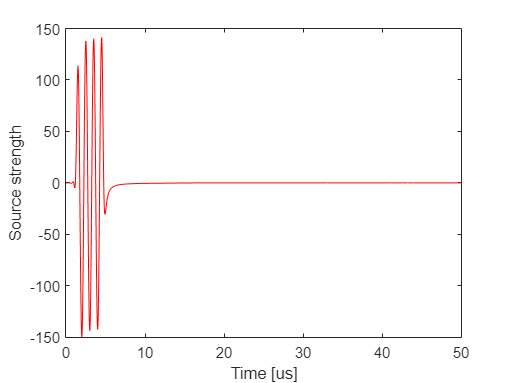

plot(Kgrid.t_array * scale, intensity, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Source strength');

%integral'
intensity_2 = intensity.^2;
Q = trapz(intensity_2)

Q = 8.5455e+05


%fun = @(x) exp(-x.^2).*log(x).^2;
fun = @(x) (coeff*sum(A)).^2

fun = 包含以下值的 function_handle :
    @(x)(coeff*sum(A)).^2


%fun_2 = fun.^2
q = integral(fun,0,5e-05,'ArrayValued',true)

q =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0004    0.0010    0.0012    0.0004    0.0004    0.0083    0.0372    0.1019    0.2097    0.3515    0.4986    0.6102    0.6484    0.5947    0.4593    0.2806    0.1134    0.0126    0.0164    0.1352    0.3490    0.6122    0.8656    1.0508


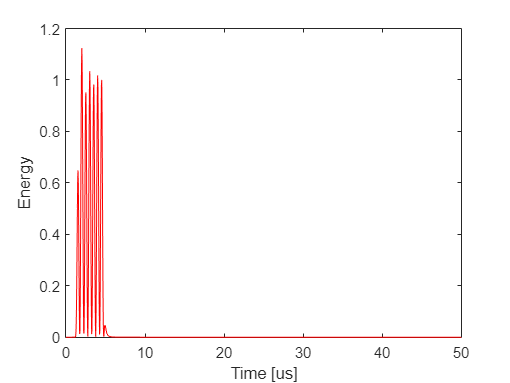

figure
plot(Kgrid.t_array * scale, q, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Energy');

%Use point per wavelength ppl to reduce dx until stable
% sensor.time_reversal_boundary_data = sum_A;
% p0_recon = kspaceFirstOrder2D(Kgrid, medium, source, sensor);
% NEW_MAP = [Nx, Ny];
% i = 1:40/120*Nx;
ppw = 3;
ppw_old = wavelength/dx

ppw_old = 37500

wavelength = 1.5/120*Nx

wavelength = 7.5000

dx_new = wavelength/ppw

dx_new = 2.5000


speed = 1500/2e-4%the sound speed in the grid format

speed = 7500000

speed*2e-4

ans = 1500

speed/3.75e6*dx

ans = 4.0000e-04

%calculation for ppw,dx,Nx
points_per_wavelength = 2

points_per_wavelength = 2

dx_old = 1500/(points_per_wavelength*3.75e6)

dx_old = 2.0000e-04

fre = 3.75e6

fre = 3750000

ppw = 1500/(fre*2e-4)

ppw = 2

Nx = round(0.12/dx)

Nx = 600


%change ppw
ppw_new  = 3
dx_new = 1500/(fre*ppw)

dx_new = 2.0000e-04


%original received signal
step(1)

检查对函数 'step' 的调用中是否存在不正确的参数数据类型或缺少参数。

%sensor_data_new(1,:) = circshift(sensor_data_test(1,:), -step);
figure
subplot(2,1,1);
plot(Kgrid.t_array * scale, sensor_data_test(1,:), 'r-');
set(gca,'XTick',[],'YTick',[]);
xlabel(['Time [' prefix 's]']);
%shifted signal
subplot(2,1,2);
plot(Kgrid.t_array * scale, sensor_data_new(1,:), 'r-');
xlabel(['Time [' prefix 's]']);

% sensor_data_new = distance * sensor_data
% figure
% subplot(2,1,1);
% plot(Kgrid.t_array * scale, sensor_data_new, 'r-');
% subplot(2,1,2);
% plot(Kgrid.t_array * scale, sensor_data(31,:), 'r-');
